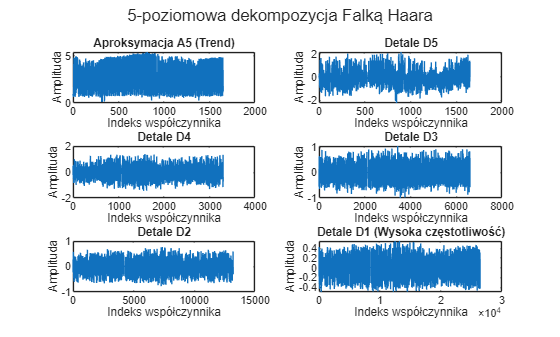

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A5 = appcoef(c, l, 'haar', 5);

% Pobierz współczynniki detali z poziomów 5, 4, 3, 2, 1
D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% 2. RYSOWANIE WYKRESÓW
figure; % Stwórz nowe okno wykresu

% Układ 3x2:
% [A5 | D5]
% [D4 | D3]
% [D2 | D1]

% --- Trend (Aproksymacja) ---
subplot(3, 2, 1);
plot(A5);
title('Aproksymacja A5 (Trend)');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D5 (Najniższa częstotliwość detali) ---
subplot(3, 2, 2);
plot(D5);
title('Detale D5');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D4 ---
subplot(3, 2, 3);
plot(D4);
title('Detale D4');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D3 ---
subplot(3, 2, 4);
plot(D3);
title('Detale D3');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D2 ---
subplot(3, 2, 5);
plot(D2);
title('Detale D2');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% --- Detale D1 (Najwyższa częstotliwość / Szum) ---
subplot(3, 2, 6);
plot(D1);
title('Detale D1 (Wysoka częstotliwość)');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

% Poprawia czytelność całego okna
sgtitle('5-poziomowa dekompozycja Falką Haara');

forecast_horizont = 32 * 100;

Mdl_A5 = arima('Seasonality', 21, ...
               'SARLags', 1, ... 
               'D', 0, 'ARLags', 2, 'MALags', 1);
EstMdl_A5 = estimate(Mdl_A5, A5);

 
    ARIMA(2,0,1) Model Seasonally Integrated with Seasonal AR(1) (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    -0.0015583      0.012277        -0.12693         0.89899
    AR{2}         -0.16561      0.020411         -8.1137      4.9088e-16
    SAR{1}         0.74717      0.021364          34.973     5.8308e-268
    MA{1}          -0.3373      0.030164         -11.182      4.9815e-29
    Variance        0.5633      0.011399          49.416               0



A5_pred = forecast(EstMdl_A5, forecast_horizont/32, 'Y0', A5);



Mdl_D4 = arima(3, 0, 0); % Przykładowy model AR(3)
EstMdl_D4 = estimate(Mdl_D4, D4);

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    -0.025119      0.0066535       -3.7753       0.00015982
    AR{1}        -0.11163       0.018475       -6.0424       1.5186e-09
    AR{2}        -0.29374       0.017157        -17.12       1.0493e-65
    AR{3}         -0.4671       0.014291       -32.685      2.5775e-234
    Variance      0.13687      0.0029887        45.795                0



D4_pred = forecast(EstMdl_D4, forecast_horizont/16, 'Y0', D4);

Mdl_D3 = arima(3, 0, 0); % Przykładowy model AR(3)
EstMdl_D3 = estimate(Mdl_D3, D3);

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0049142      0.0032251       -1.5237         0.12758
    AR{1}        -0.043195       0.017442       -2.4765         0.01327
    AR{2}         -0.14117       0.011772       -11.992      3.9098e-33
    AR{3}        -0.020163       0.012558       -1.6056         0.10836
    Variance      0.060043      0.0007609         78.91               0



D3_pred = forecast(EstMdl_D3, forecast_horizont/8, 'Y0', D3);

Mdl_D2 = arima(4, 0, 0); % Przykładowy model AR(4)
EstMdl_D2 = estimate(Mdl_D2, D2);

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0019462      0.0014106       -1.3797         0.16769
    AR{1}         -0.16492       0.010305       -16.005      1.1872e-57
    AR{2}        -0.034369       0.014165       -2.4263        0.015252
    AR{3}         -0.05056        0.01415       -3.5732       0.0003526
    AR{4}         -0.13905      0.0072829       -19.093      2.8667e-81
    Variance      0.020748     0.00013671        151.77               0



D2_pred = forecast(EstMdl_D2, forecast_horizont/4, 'Y0', D2);

Mdl_D1 = arima(5, 0, 0); % Przykładowy model AR(5)
EstMdl_D1 = estimate(Mdl_D1, D1);

 
    ARIMA(5,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0004482     0.00052719        0.85017        0.39523
    AR{1}         -0.25962      0.0041631        -62.361              0
    AR{2}        -0.097148      0.0091643        -10.601     2.9571e-26
    AR{3}        -0.032251       0.011332        -2.8461      0.0044259
    AR{4}        -0.012107       0.011889        -1.0183        0.30853
    AR{5}       -0.0020976       0.011283       -0.18591        0.85252
    Variance     0.0057758     2.0619e-05         280.12              0



D1_pred = forecast(EstMdl_D1, forecast_horizont/2, 'Y0', D1);

D5_pred = zeros(forecast_horizont/32, 1);

c_pred_5 = [A5_pred', D5_pred'];
l_pred_5 = [length(A5_pred), length(D5_pred), length(A5_pred) + length(D5_pred)];
pred_5 = waverec(c_pred_5, l_pred_5, 'haar');

c_pred_4 = [pred_5, D4_pred'];
l_pred_4 = [length(pred_5), length(D4_pred), length(pred_5) + length(D4_pred)];
pred_4 = waverec(c_pred_4, l_pred_4, 'haar');

c_pred_3 = [pred_4, D3_pred'];
l_pred_3 = [length(pred_4), length(D3_pred), length(pred_4) + length(D3_pred)];
pred_3 = waverec(c_pred_3, l_pred_3, 'haar');

c_pred_2 = [pred_3, D2_pred'];
l_pred_2 = [length(pred_3), length(D2_pred), length(pred_3) + length(D2_pred)];
pred_2 = waverec(c_pred_2, l_pred_2, 'haar');

c_pred_1 = [pred_2, D1_pred'];
l_pred_1 = [length(pred_2), length(D1_pred), length(pred_2) + length(D1_pred)];
pred_1 = waverec(c_pred_1, l_pred_1, 'haar');

pred_full = pred_1;

y_test = ab_diff_test_norm(1:length(pred_full))';

mae_1 = mae(y_test, pred_full)

mae_1 = 0.2534

mape_1 = mape(y_test, pred_full)

mape_1 = 117.7304

rmse_1 = rmse(y_test, pred_full)

rmse_1 = 0.3353

r2_classic = R2_classic(y_test, pred_full)

r2_classic = 0.0488

r2_alt = R2_alt(y_test, pred_full)

r2_alt = 0.4542

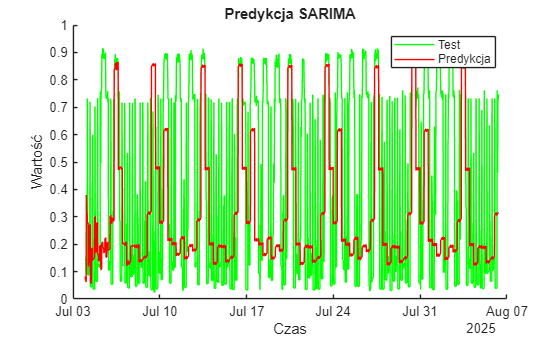


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(pred_full)), ab_diff_test_norm(1:length(pred_full)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(pred_full)), pred_full, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja SARIMA")
legend;